%% https://users.aalto.fi/~ktlokki/sdm_tools.html
clc
clear all

[ir_right(:,1),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic1.wav');
[ir_right(:,2),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic2.wav');
[ir_right(:,3),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic3.wav');
[ir_right(:,4),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic4.wav');
[ir_right(:,5),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic5.wav');
[ir_right(:,6),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic6.wav');

[ir_left(:,1),fs] = audioread('testData\IRs_valerio\pos_-1_speaker_1\ir_pos_-1_speaker_1_mic1.wav');
[ir_left(:,2),fs] = audioread('testData\IRs_valerio\pos_-1_speaker_1\ir_pos_-1_speaker_1_mic2.wav');
[ir_left(:,3),fs] = audioread('testData\IRs_valerio\pos_-1_speaker_1\ir_pos_-1_speaker_1_mic3.wav');
[ir_left(:,4),fs] = audioread('testData\IRs_valerio\pos_-1_speaker_1\ir_pos_-1_speaker_1_mic4.wav');
[ir_left(:,5),fs] = audioread('testData\IRs_valerio\pos_-1_speaker_1\ir_pos_-1_speaker_1_mic5.wav');
[ir_left(:,6),fs] = audioread('testData\IRs_valerio\pos_-1_speaker_1\ir_pos_-1_speaker_1_mic6.wav');

url = 'dataDemoBinauralRendering/sndfld.zip';
tic
hrtfnames = unzip(url,'.'); % <--- Unzip to this (.) folder
tc = toc;
disp(hrtfnames')

    {'sndfld\'                       }
    {'sndfld\readme.txt'             }
    {'__MACOSX\'                     }
    {'__MACOSX\sndfld\'              }
    {'__MACOSX\sndfld\._readme.txt'  }
    {'sndfld\s1_r1_sf.wav'           }
    {'__MACOSX\sndfld\._s1_r1_sf.wav'}
    {'sndfld\s1_r2_sf.wav'           }
    {'__MACOSX\sndfld\._s1_r2_sf.wav'}
    {'sndfld\s1_r3_sf.wav'           }
    {'__MACOSX\sndfld\._s1_r3_sf.wav'}
    {'sndfld\s1_r4_sf.wav'           }
    {'__MACOSX\sndfld\._s1_r4_sf.wav'}
    {'sndfld\s2_r1_sf.wav'           }
    {'__MACOSX\sndfld\._s2_r1_sf.wav'}
    {'sndfld\s2_r2_sf.wav'           }
    {'__MACOSX\sndfld\._s2_r2_sf.wav'}
    {'sndfld\s2_r3_sf.wav'           }
    {'__MACOSX\sndfld\._s2_r3_sf.wav'}
    {'sndfld\s2_r4_sf.wav'           }
    {'__MACOSX\sndfld\._s2_r4_sf.wav'}
    {'sndfld\s3_r1_sf.wav'           }
    {'__MACOSX\sndfld\._s3_r1_sf.wav'}
    {'sndfld\s3_r2_sf.wav'           }
    {'__MACOSX\sndfld\._s3_r2_sf.wav'}
    {'sndfld\s3_r3_sf.wav

disp(['Ended downloading and unzipping in ' num2str(tc) ' seconds'])

Ended downloading and unzipping in 0.19949 seconds


% Read stereo signal
S = audioread(['dataDemoBinauralRendering\killJill.mp3']);
% Choose 10 seconds and resample
Sr = resample(S(1:44.e3*10,:),480,441);

fs = 192e3;
a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 192000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



DOA{1} = SDMPar(ir_left, a);

Started SDM processing
Using frame size 64
Ended SDM processing in 32.8167 seconds.



% Here we are using the top-most microphone as the estimate for the
% pressure in the center of the array
P{1} = ir_left(:,5);

% Same for right channel
DOA{2} = SDMPar(ir_right, a);

Started SDM processing
Using frame size 64
Ended SDM processing in 31.1948 seconds.


P{2} = ir_right(:,5);

v = createVisualizationStruct('DefaultRoom','VerySmall',...
    'name','Home Control Room','fs',fs);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 192000
           plane: 'lateral'
             DOI: 'backward'
       plotStyle: 'fill'
            name: 'Home Control Room'
             res: 1
               t: [0 2 5 20]
          colors: [4×3 double]
       dBSpacing: [-12 -6 0]
      DOASpacing: 30
       linewidth: [0 0 0 0]
        showGrid: 1
      dBDynamics: 36
    smoothMethod: 'average'
       smoothRes: 3



% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')

Started visualization of parameters.


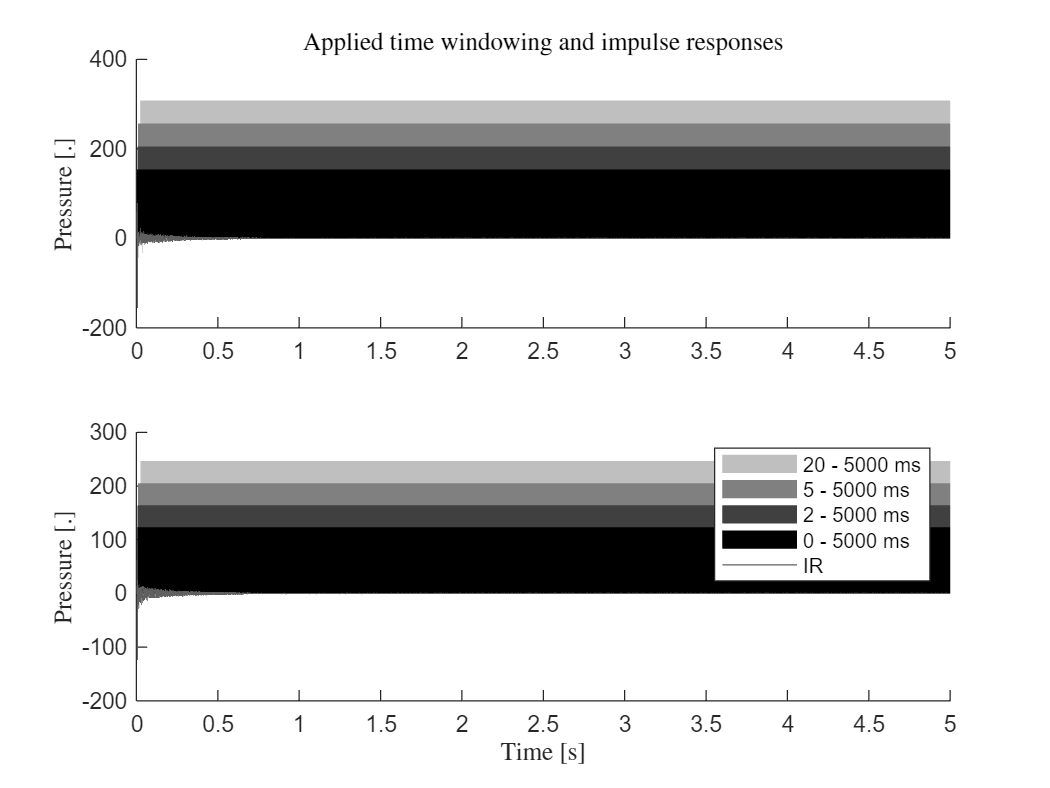

Ended visualization of parameters in 2.3622 seconds.


parameterVisualization(P, v);

Started time-frequency visualization.


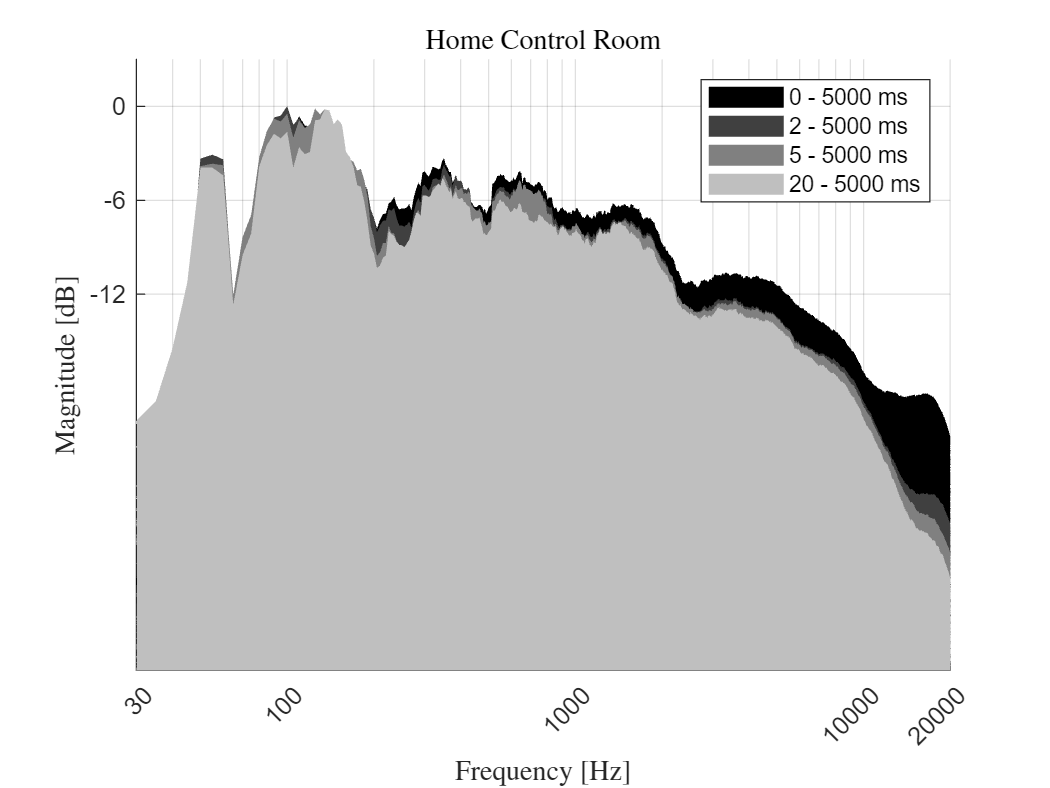

Ended time-frequency visualization in 3.8495 seconds.


timeFrequencyVisualization(P, v)

Started spatio-temporal visualization.


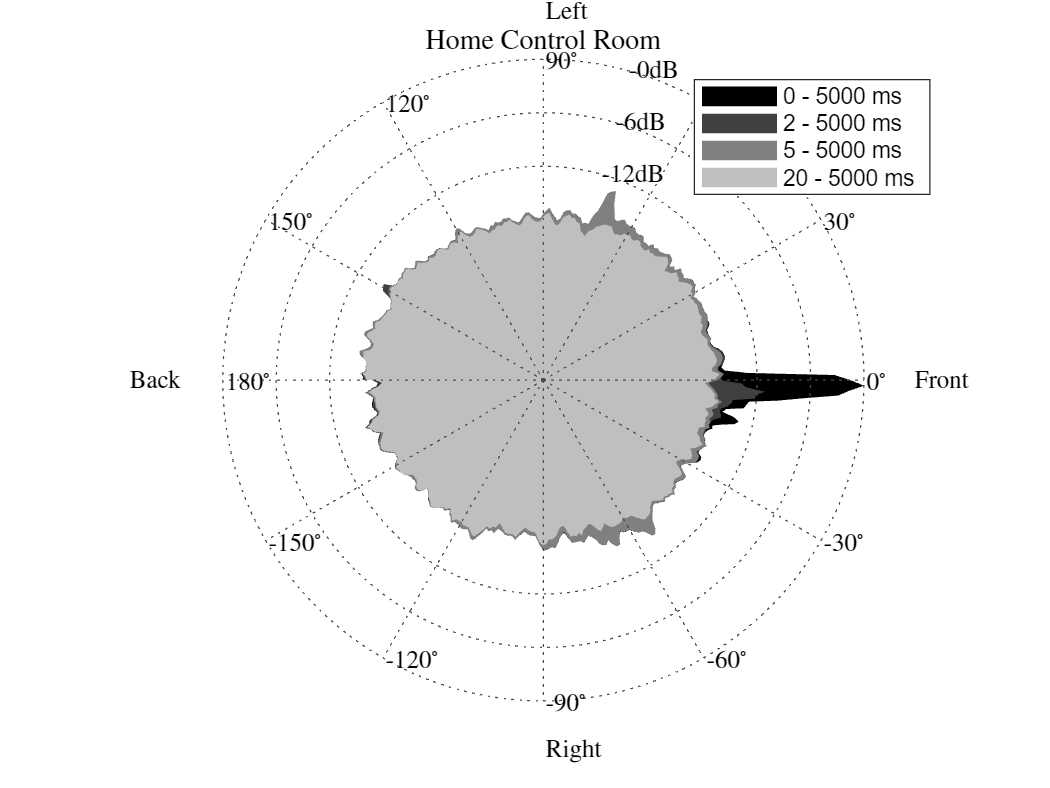

Ended spatio-temporal visualization in 10.8964 seconds.


ans = 0

v.plane = 'lateral';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


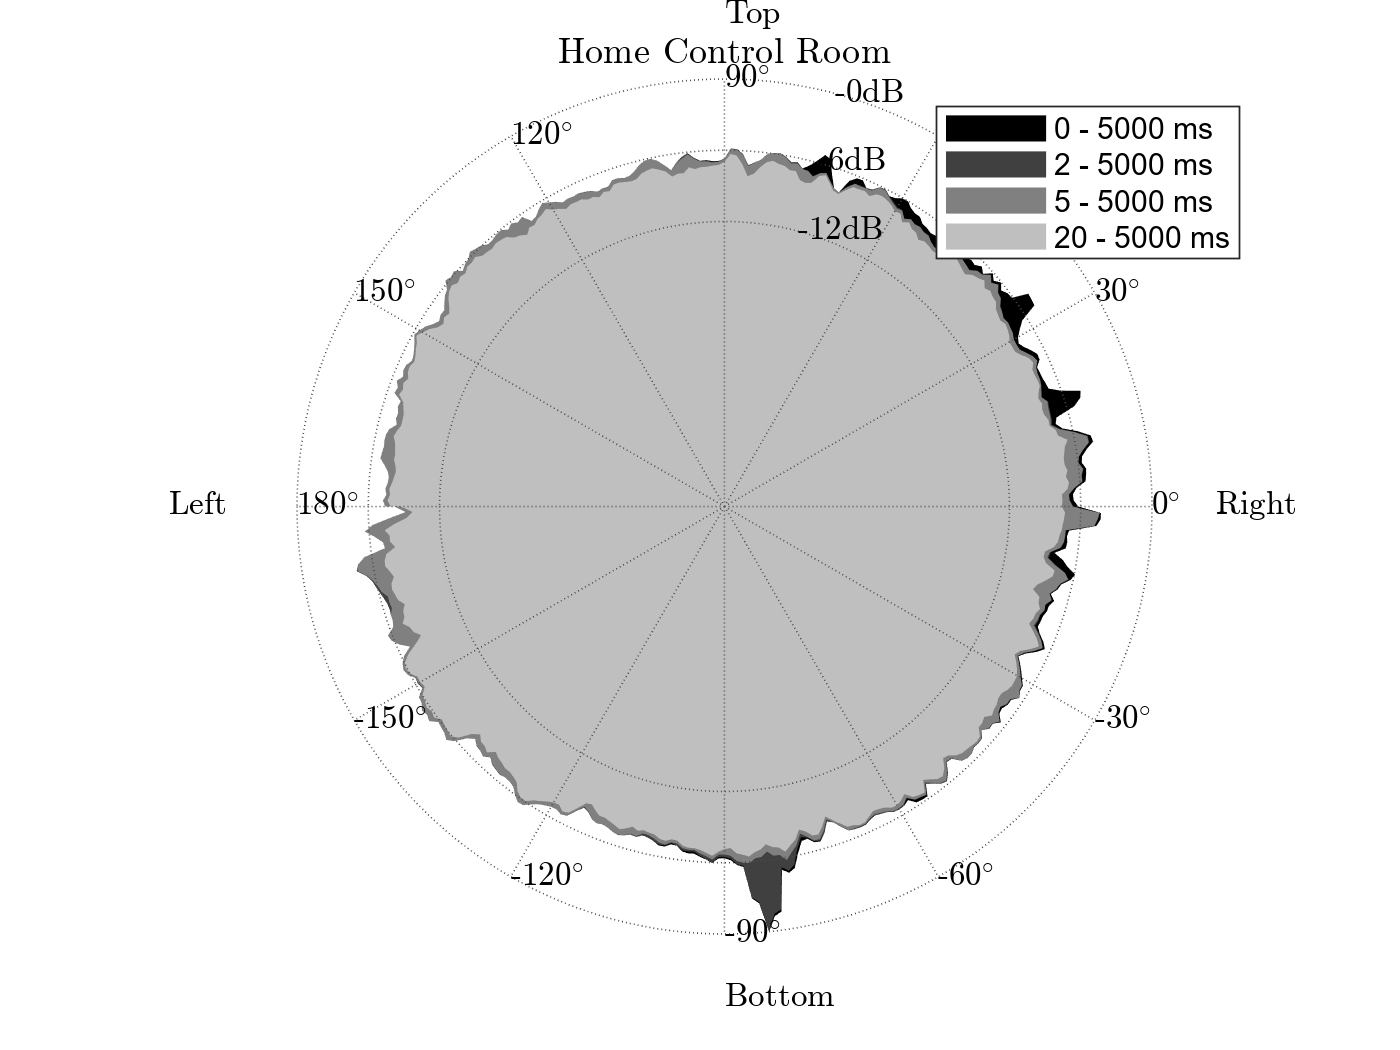

Ended spatio-temporal visualization in 9.6254 seconds.


ans = 83

v.plane = 'transverse';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


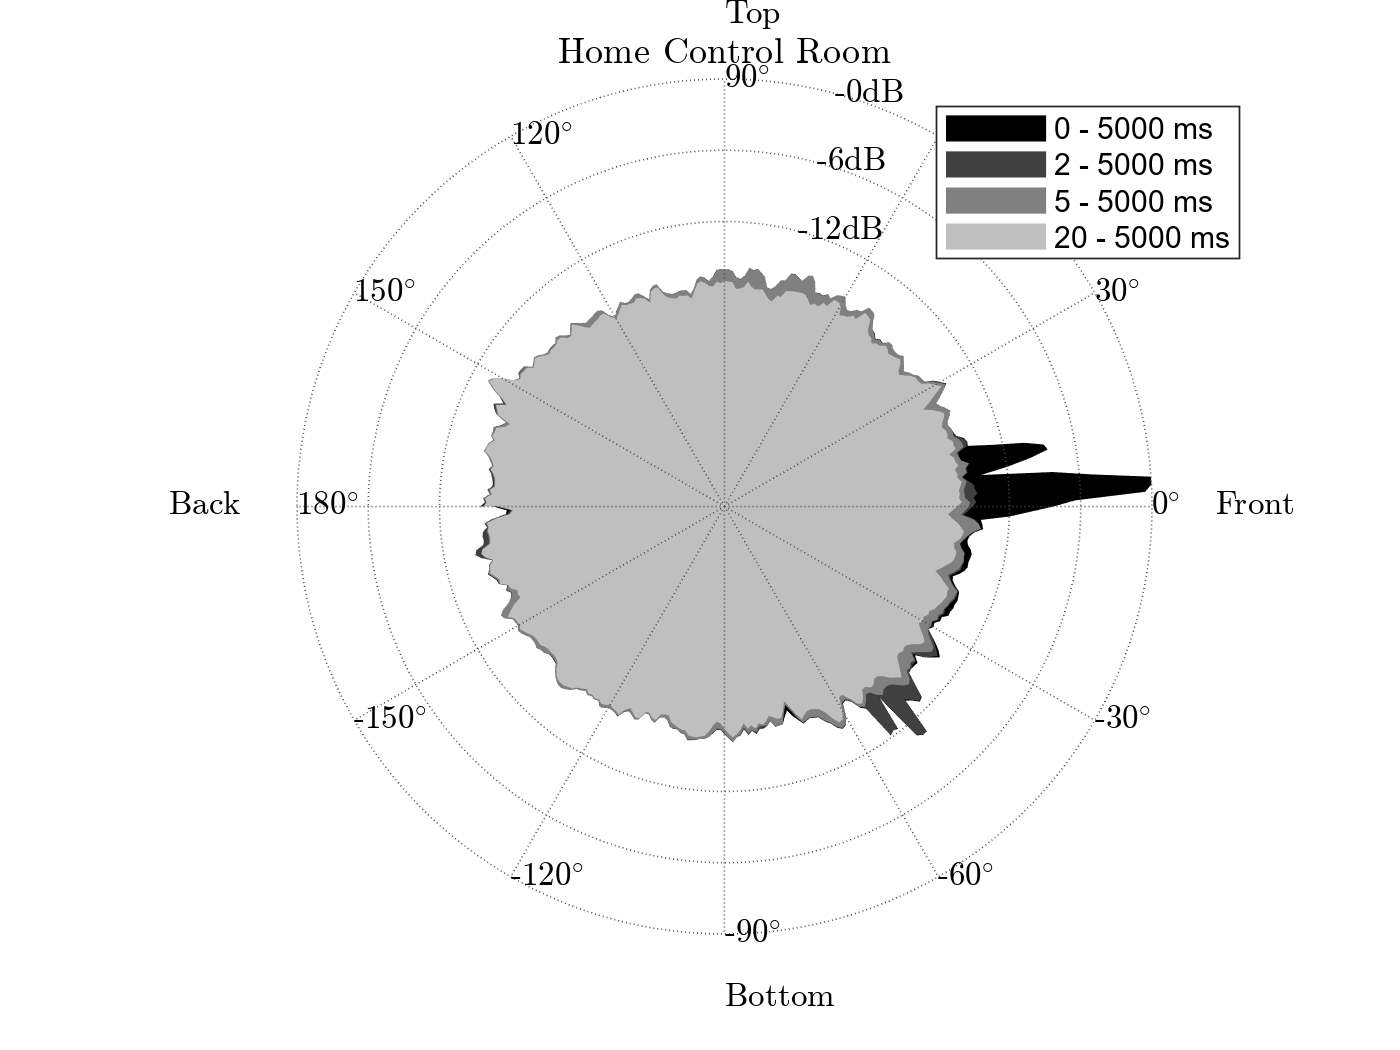

Ended spatio-temporal visualization in 9.5538 seconds.


ans = -5

v.plane = 'median';
spatioTemporalVisualization(P, DOA, v)

lspSetupNames = {'2.1','5.1','22.2','AALTO_24'};
for lspSetups = 1:length(lspSetupNames)
        % load default 5.1 setup and define some parameters with custom values
    s = createSynthesisStruct('Binaural',true,...
        'DefaultArray',lspSetupNames{lspSetups},...
        'HRTFset',28,... % <---- CIPIC HRTF subject number
        'snfft',length(P{1}),...
        'fs',192e3,...
        'c',343);
    % You always need to define 'snfft'
        Hbin = cell(1,2);
    H = cell(1,2);
    for channel = 1:2
        [~, Hbin{channel}] = synthesizeSDMCoeffs(P{channel},DOA{channel}, s);
    end

    % Resample H to 48e3 [Hz] sampling frequency for auralization
    Hbin{1} = resample(Hbin{1},1,4);
    Hbin{2} = resample(Hbin{2},1,4);
    
    Y = zeros(size(Sr,1),2);
    for channel = 1:2 % measured left and right channel
        for lsp = 1:2 % left and right ear
            % Convolution with Matlab's overlap-add
            Y(:,lsp) = Y(:,lsp) +  fftfilt(Hbin{channel}(:,lsp),Sr(:,channel));
        end
    end
    % Y contains the auralization of the spatial IRs with S

    disp('Started Auralization');tic
    savename = [ir_filename '_' audio_filename '_Binaural_' lspSetupNames{lspSetups} '.wav'];
    if max(abs(Y(:))) > 1
        Y = Y/max(abs(Y(:)))*.9;
        disp('Sound normalized, since otherwise would have clipped')
    end
    disp(['Ended Auralization in ' num2str(toc) ' seconds.'])
    disp('Started writing the auralization wav file')
    disp([savename  ' on the disk.']);tic
    audiowrite(savename,Y/10,s.fs/4) % <---- save the result as wav
    info = audioinfo(savename);
    disp('Wrote ... ');
    disp(info)
    disp(['... in ' num2str(toc) ' seconds'])
end

Error using load
Unable to find file or directory 'CIPIC_hrtf_database\standard_hrir_database\subject_028\hrir_final.mat'.

Error in createSynthesisStruct (line 431)
    load([cipic_path 'subject_' cipic_name fp 'hrir_final.mat'])